subjective_probs = modified_gaussian_inverse_cdf(rand(1,1e3),5/10,1/10);
bet_amounts = round(100*rand(1,1e3),2); % Assuming Bet Amounts were Inedependent of Subjective Probability
assert(length(subjective_probs)==length(bet_amounts))
x = 2;


% Mark 1

[player_struct,~] = mark_1_gambling_system(subjective_probs,bet_amounts,x);
mark1_system_metrics = gambling_system_checker(player_struct,bet_amounts)

mark1_system_metrics = struct with fields:
             dollar_accountability: 1
                    peer_bets_work: 1
                   moneyline_works: 1
                  peer2peer_profit: 3.0646e+03
                  moneyline_profit: 205.3100
                      total_profit: 3.2699e+03
                     profit_margin: 0.0662
    subjective_expectation_created: 3.2034e+03
                       effective_x: 1.9133
                  waste_proportion: 0.0063
           subjective_expectations: [4.9931 1.7066 5.1778 3.0118 0.0239 3.5671 5.8765 1.6860 0.1252 6.6559 3.6259 0.3176 1.6789 0.1005 0.3603 4.2602 6.8242 4.0898 0.2415 8.5906 0.4129 0.1352 3.2706 8.6776 2.2903 0.9436 3.0497 2.7091 … ] (1×1000 double)
    subjective_standard_deviations: [62.5084 24.3487 29.7232 93.0727 0.2931 37.7892 69.4729 31.4022 0.8034 80.3081 85.6068 7.6965 73.4925 1.5553 7.6753 22.2353 59.2490 26.6235 3.8746 55.3938 53.9397 14.6936 49.2493 83.9191 92.3421 … ] (1×1000 double)


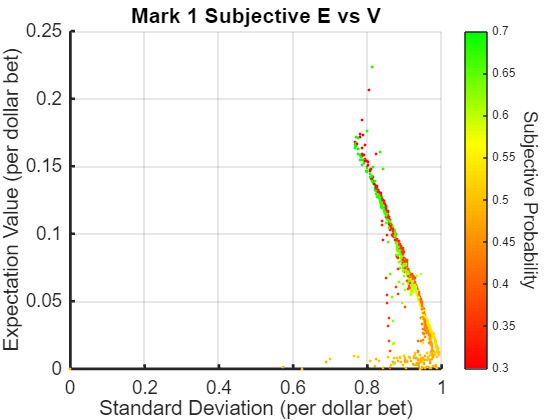


figure
hold on
for index = 1:length(subjective_probs)
    prob_percentile = sum(subjective_probs<subjective_probs(index))/length(subjective_probs);
    red_value = min(3-3*prob_percentile,1);
    green_value = min(3/2*prob_percentile,1);
    blue_value = 0;
    plot_color = [red_value,green_value,blue_value]; 
    expected_value = mark1_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = mark1_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',plot_color)
end
xlabel('Standard Deviation (per dollar bet)','FontSize',16)
ylabel('Expectation Value (per dollar bet)','FontSize',16)
title('Mark 1 Subjective E vs V')
sexy_plot

% Colorbar
the_colorbar = colorbar('Ticks',.3:.05:.7);
clim([.3 .7])
prob_values = 0:.01:1;
red_values = min(3-3*prob_values,1)';
green_values = min(3/2*prob_values,1)';
blue_values = zeros(1,length(prob_values))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Subjective Probability','Rotation',270,'FontSize',14)
hold off

% Money Line

[player_struct,~] = moneyline_gambling_system(subjective_probs,bet_amounts);
moneyline_system_metrics = gambling_system_checker(player_struct,bet_amounts)

moneyline_system_metrics = struct with fields:
             dollar_accountability: 1
                    peer_bets_work: 1
                   moneyline_works: 1
                  peer2peer_profit: 0
                  moneyline_profit: 2.8583e+03
                      total_profit: 2.8583e+03
                     profit_margin: 0.0579
    subjective_expectation_created: 1.9241e+03
                       effective_x: 0
                  waste_proportion: 0.5196
           subjective_expectations: [1.6367 0.1604 6.0468 0 0.0239 1.9158 2.0426 0 0.1317 2.3457 0 0 0 0.1126 0 5.1702 5.3287 4.4071 0 9.4417 0 0 0 5.7966 0 0.9187 0 0.1931 1.3359 12.1248 0 0.6671 0 0 0 0.0436 3.9581 0 0 0 1.0215 0 … ] (1×1000 double)
    subjective_standard_deviations: [59.6622 23.0130 30.3423 0 0.2931 36.4240 66.2400 0 0.8082 76.6647 0 0 0 1.5650 0 22.8680 58.0605 26.8576 0 56.0188 0 0 0 81.5863 0 8.1129 0 37.0813 33.4193 77.5051 0 18.9095 0 0 0 32.8243 63.0236 0 … ] (1×1000 double)


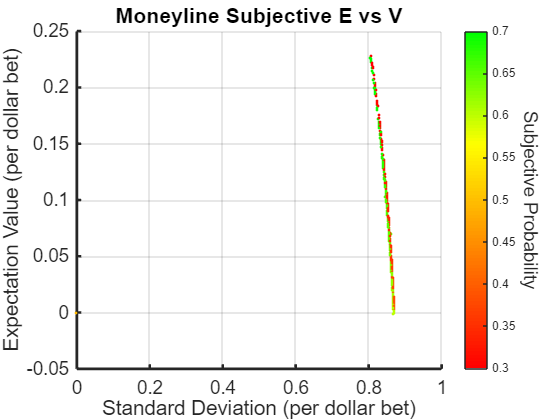


figure
hold on
for index = 1:length(subjective_probs)
    prob_percentile = sum(subjective_probs<subjective_probs(index))/length(subjective_probs);
    red_value = min(3-3*prob_percentile,1);
    green_value = min(3/2*prob_percentile,1);
    blue_value = 0;
    plot_color = [red_value,green_value,blue_value]; 
    expected_value = moneyline_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = moneyline_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',plot_color)
end
xlabel('Standard Deviation (per dollar bet)','FontSize',16)
ylabel('Expectation Value (per dollar bet)','FontSize',16)
title('Moneyline Subjective E vs V')
sexy_plot

% Colorbar
the_colorbar = colorbar('Ticks',.3:.05:.7);
clim([.3 .7])
prob_values = 0:.01:1;
red_values = min(3-3*prob_values,1)';
green_values = min(3/2*prob_values,1)';
blue_values = zeros(1,length(prob_values))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Subjective Probability','Rotation',270,'FontSize',14)
hold off

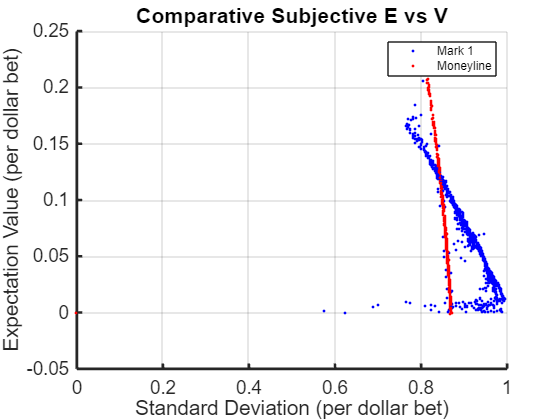

% Direct Comparison of Expectation Values and Standard Deviations

figure
hold on
for index = 1:length(subjective_probs)

    % Mark 1
    expected_value = mark1_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = mark1_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    if index == 1
        mark1_plot = plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[0 0 1]);
    else
        plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[0 0 1]);
    end

    % Money Line
    expected_value = moneyline_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = moneyline_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    if index == 1
        moneyline_plot = plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[1 0 0]);
    else
        plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[1 0 0])
    end

end
xlabel('Standard Deviation (per dollar bet)','FontSize',16)
ylabel('Expectation Value (per dollar bet)','FontSize',16)
title('Comparative Subjective E vs V')
legend([mark1_plot,moneyline_plot],{'Mark 1','Moneyline'})
sexy_plot
hold off

% Betting Exchange

[player_struct] = betting_exchange_gambling_system(subjective_probs,bet_amounts,40)

player_struct = 1×1000 struct array with fields:
    player_number
    player_probability
    peer2peer_win_conditions
    peer2peer_bet_amounts
    peer2peer_pots
    matched_players
    match_numbers
    moneyline_win_condition
    moneyline_pbeta
    moneyline_palpha
    moneyline_bet_amount
    remaining_money
    moneyline_earnings


betting_exchange_system_metrics = gambling_system_checker(player_struct,bet_amounts)

Moneyline Profit - Focal: 8.295000e+02, Compliment: 1.260500e+02 


betting_exchange_system_metrics = struct with fields:
             dollar_accountability: 1
                    peer_bets_work: 1
                   moneyline_works: 0
                  peer2peer_profit: 0
                  moneyline_profit: 126.0500
                      total_profit: 126.0500
                     profit_margin: 0.0026
    subjective_expectation_created: 6.5975e+03
                       effective_x: 0
                  waste_proportion: 0.0370
           subjective_expectations: [9.8852 3.7510 11.7918 4.9360 0.0664 7.0835 12.6383 2.9025 0.2609 12.9842 7.4726 0.6651 2.7132 0.3361 0.7379 9.0262 13.8972 9.3158 0.4383 19.7321 0.0243 0.2190 5.8637 19.3863 3.4176 2.1397 4.9991 … ] (1×1000 double)
    subjective_standard_deviations: [66.6569 26.1148 34.4345 94.8684 0.3273 40.6964 75.1749 32.4961 0.9038 85.6574 89.1335 8.0153 74.4867 1.7460 8.0188 25.5490 64.8700 30.4787 4.0482 63.5757 57.1296 17.5223 51.5249 92.5903 93.4106 … ] (1×1000 double)


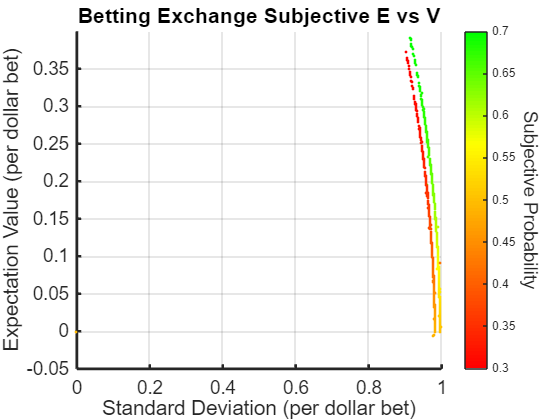


figure
hold on
for index = 1:length(subjective_probs)
    prob_percentile = sum(subjective_probs<subjective_probs(index))/length(subjective_probs);
    red_value = min(3-3*prob_percentile,1);
    green_value = min(3/2*prob_percentile,1);
    blue_value = 0;
    plot_color = [red_value,green_value,blue_value]; 
    expected_value = betting_exchange_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = betting_exchange_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',plot_color)
end
xlabel('Standard Deviation (per dollar bet)','FontSize',16)
ylabel('Expectation Value (per dollar bet)','FontSize',16)
title('Betting Exchange Subjective E vs V')
sexy_plot

% Colorbar
the_colorbar = colorbar('Ticks',.3:.05:.7);
clim([.3 .7])
prob_values = 0:.01:1;
red_values = min(3-3*prob_values,1)';
green_values = min(3/2*prob_values,1)';
blue_values = zeros(1,length(prob_values))';
colormap([red_values, green_values, blue_values])
ylabel(the_colorbar,'Subjective Probability','Rotation',270,'FontSize',14)
hold off

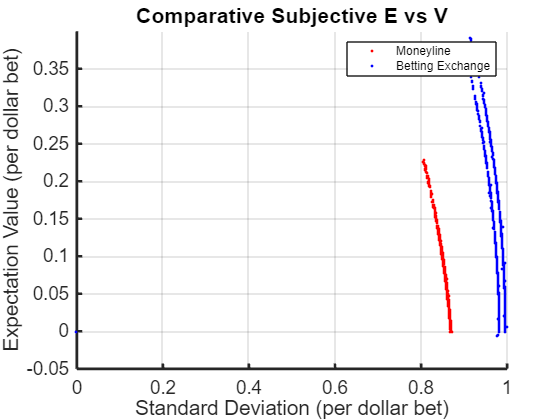

% Direct Comparison of Expectation Values and Standard Deviations

figure
hold on
for index = 1:length(subjective_probs)

    % Money Line
    expected_value = moneyline_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = moneyline_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    if index == 1
        moneyline_plot = plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[1 0 0]);
    else
        plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[1 0 0])
    end

    % Betting Exchange
    expected_value = betting_exchange_system_metrics.subjective_expectations(index)/bet_amounts(index);
    standard_deviation = betting_exchange_system_metrics.subjective_standard_deviations(index)/bet_amounts(index);
    if index == 1
        betting_exchange_plot = plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[0 0 1]);
    else
        plot(standard_deviation,expected_value,'LineStyle','none','Marker','.','Color',[0 0 1]);
    end

end
xlabel('Standard Deviation (per dollar bet)','FontSize',16)
ylabel('Expectation Value (per dollar bet)','FontSize',16)
title('Comparative Subjective E vs V')
legend([moneyline_plot,betting_exchange_plot],{'Moneyline','Betting Exchange'})
sexy_plot
hold off

% Comparing Expectation Values Across Subjective Probabilities

mark1_expected_values = mark1_system_metrics.subjective_expectations./bet_amounts;
moneyline_expected_values = moneyline_system_metrics.subjective_expectations./bet_amounts;
betting_exchange_expected_values = betting_exchange_system_metrics.subjective_expectations./bet_amounts;
[~,sort_indeces] = sort(subjective_probs);

figure
hold on
plot(subjective_probs(sort_indeces),moneyline_expected_values(sort_indeces))
plot(subjective_probs(sort_indeces),betting_exchange_expected_values(sort_indeces))
plot(subjective_probs(sort_indeces),mark1_expected_values(sort_indeces))
xlabel('Subjective Probability (per dollar bet)','FontSize',16)
ylabel('Subjective Expectation Value (per dollar bet)','FontSize',16)
title('Comparative Subjective Expectation Value')
legend({'Moneyline','Betting Exchange','Mark 1'})
sexy_plot
